# Lab 7

In this lab we continue working on the video encoder implementation.

Now we can use the function completed last week and run the video encoder in Intra only configuration. 

In order to do that, create the files `sequenceEncoder.m `and `gopEncoder.m `as described in lab 6, and use the following to test the video codec in intra only configuration:

clear variables
global params img decodedFrameBuffer

params.IntraQualityFactorVector = 20:20:80;
params.deltaQ = 10; % The QF of Inter frame is  smaller than that of INTRA
params.inputVideoName = 'bus'; % Use one of the provided .y files
params.inputVideoFile   = [params.inputVideoName '_cif.y']   % full input file name. Add the path if needed

params = struct with fields:
           quantizationSteps: 20
              inputVideoName: 'bus'
              inputVideoFile: 'bus_cif.y'
         modeSelectionLabmda: 10
      motionEstimationLambda: 3
                          ME: [1×1 struct]
                     GOPSize: 1
                   blockSize: 8
                        nRow: 288
                        nCol: 352
                     verbose: 1
               firstFrameGOP: 11
                         fid: 5
                        qual: 80
                       q_mtx: [8×8 double]
    IntraQualityFactorVector: [20 40 60 80]
                      deltaQ: 10


params.GOPSize = 1; % Start with an "All Intra" configuration. Then move to IPP..P  Gops
params.numberOfGops = 3; % Start with a small number of GOPS for test, then use the full sequence
params.blockSize = 8;  % 
params.nRow = 288;
params.nCol = 352;
params.verbose = 0;  % Setting the verboseness level might be useful for debugging and testing
% other possible parameters can be set as fields of the struct
decodedFrameBuffer.reference = zeros(params.nRow,params.nCol); % Since we do not use B, one decoded refernce is enough
decodedFrameBuffer.current   = zeros(params.nRow,params.nCol); % We also need a buffer for the current encoded image
params.compressedFileName = 'test.bin'; 

nEncodings = numel(params.IntraQualityFactorVector);
PSNR = zeros(nEncodings, 1); 
RATE = zeros(nEncodings, 1); 

%% Init for compression
params.q_mtx1 =     [16 11 10 16 24 40 51 61; 
            12 12 14 19 26 58 60 55;
            14 13 16 24 40 57 69 56; 
            14 17 22 29 51 87 80 62;
            18 22 37 56 68 109 103 77;
            24 35 55 64 81 104 113 92;
            49 64 78 87 103 121 120 101;
            72 92 95 98 112 100 103 99];


%% Main loop
for qualityIndex = 1:nEncodings
    QF = params.IntraQualityFactorVector(qualityIndex)
    params.qual =  QF;
    [R, P] = sequenceEncoder(); %don't need input arg because param is global!
    RATE(qualityIndex) = R;
    PSNR(qualityIndex) = P;
end

QF = 20

QF = 40

QF = 60

QF = 80

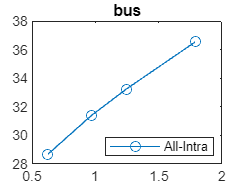


% Show the results
plot(RATE, PSNR, 'o-') ;
title(params.inputVideoName)
legend('All-Intra','Location','southeast');

You should obtain rates around 0.4 to 1.2 bpps and PSNR in the range 30-40 dB for "foreman" and similar values for the other sequences. 

## Motion Estimation

The core of the Inter coding step lies in the motion estimation function. 

We want to implement a motion estimation function with the following features:

The input is a **block** of the current image. The coordinates of the block are stored in the global variable `params`.

There are two output parameters: the best-matching **block** (i.e., the *predictor* of the current block) and the estimated motion vector.

Within the motion estimation function, we use the global variable `decodedFrameBuffer.reference` to access to the reference image. We also use a new global variable, `MVF`, which is useful to store the already estimated motion vector. 

The ME criterion is a regularized SAD. The regulatization term is the coding cost of the motion vector. The motion vector is encoded with spatial prediction and signed Exp-Golomb. **Notice that this is the same ME technique that we used in Lab. no 5. **

All the parameters of the motion estimation are stored in the global variable `params.ME`

Here we provide: first the skeleton code for the motion estimation function; and second, a testing environment for the function. 

**QUESTION 1. Complete the code of the **`motionEstimation.m `**function (remember to copy/past the following code in a new file, and then complete the missing parts). Test the function in the next environment. **

The `motionEstimation` function can be tested in the following environment.

**QUESTION 2. Open the provided **`loadInter.m `**function, and understand its operation. Describe precisely its input and output parameters. **

clear variables
global params img decodedFrameBuffer MVF 

% Setting the configuration
params.inputVideoName = 'flower'; % Use one of the provided .y files
params.inputVideoFile   = [params.inputVideoName '_cif.y'];   % full input file name. Add the path if needed
params.blockSize = 8;  % 
params.nRow = 288;
params.nCol = 352;
params.verbose = 2;  % Setting the verboseness level might be useful for debugging and testing
decodedFrameBuffer.reference = zeros(params.nRow,params.nCol); % Since we do not use B, one decoded refernce is enough
decodedFrameBuffer.current   = zeros(params.nRow,params.nCol); % We also need a buffer for the current encoded image
MVF = zeros(params.nRow,params.nCol,2);
params.ME.lambda = 10;
params.ME.radius = 20;

% Let us load two images from GOP 1
gopIndex = 1; 
params.GOPSize = 10; 
interIndex = 5; 
params.firstFrameGOP =  params.GOPSize*(gopIndex-1) + 1;
img = loadIntra(gopIndex);

Loading Intra image from GOP 001 (image no 001 in the file)


ref =  loadInter(gopIndex,interIndex);

Loading Inter image   5 from GOP 001 (image no 006 in the file)


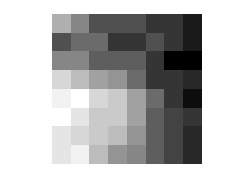


%figure; imagesc([img;ref]); colormap("gray"); axis image; axis off; 
% For the sake of simplicity, we put the original ref in the
% decodedFrameBuffer
decodedFrameBuffer.reference= ref; 

% let us take a block from the current image
params.colIndex = 164; params.rowIndex=129;
currentBlock = img(params.rowIndex:params.rowIndex+7,params.colIndex:params.colIndex+7); 
figure; imagesc([currentBlock]); colormap("gray"); axis image; axis off; 

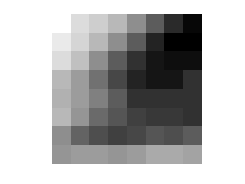

[bestMatch, mv] = motionEstimation(currentBlock);
figure; imagesc([bestMatch]); colormap("gray"); axis image; axis off; 

fprintf('The best MV is (%d,%d)\nThe PSNR is %5.2f\n', mv(1),  mv(2), ypsnr(currentBlock,bestMatch));

The best MV is (1,18)
The PSNR is 29.67


**QUESTION 3. Try the motion estimation with several blocks/images/sequences. As a reference when we take images 1 and 6 from the video sequence "flower" , for the block in position 164,129 from the sequence "flower", the best vector is (1,-4), with a PSNR=24.32 dB. **

**Test other blocks and positions. **

**akiyo **

`     The best MV is (0,0)`

`     The PSNR is 46.37`

`bus`

          `The best MV is (7,17)`

`     The PSNR is 18.94`

`foreman`

`     The best MV is (1,18)`

`     The PSNR is 29.67`

## Inter block coding

Now we can implement the function that encodes a block in Inter mode. We can take inspiration from the `blockIntraCoding` function, and suitably adapt it to the case of Inter coding.

Now we have to implement the `blockInterCoding `function. Here we must first find the best temporal predictor by using motion estimation; then we have to encode the prediction error in a JPEG-like fashion. Here you can find the code to complete in order to achieve the function. As usual, copy past in a new file, and complete the missing parts. 

**QUESTION 4. Complete the **`blockInterCoding.m `**function (copy/past into a new file, complete the missing parts) and test it in the provided test environment. **

Let us test the block inter coding function. 

clear variables; 
clc
global params img decodedFrameBuffer MVF 

% Setting the configuration
params.inputVideoName = 'akiyo'; % Use one of the provided .y files
params.inputVideoFile   = [params.inputVideoName '_cif.y'] ;  % full input file name. Add the path if needed
params.blockSize = 8;  % 
params.nRow = 288;
params.nCol = 352;

decodedFrameBuffer.reference = zeros(params.nRow,params.nCol); % Since we do not use B, one decoded refernce is enough
decodedFrameBuffer.current   = zeros(params.nRow,params.nCol); % We also need a buffer for the current encoded image
MVF = zeros(params.nRow,params.nCol,2);
params.ME.lambda = 10;
params.ME.radius = 20;

% Let us load two images from GOP 1
gopIndex = 1; 
params.GOPSize = 10; 
interIndex = 1;  % The first inter frame
params.firstFrameGOP =  params.GOPSize*(gopIndex-1) + 1;
intra = loadIntra(gopIndex);
img =  loadInter(gopIndex,interIndex);

% For the sake of simplicity, we put the original intra frame (and not a decoded version) in the
% decodedFrameBuffer
decodedFrameBuffer.reference= intra; 

% let us take a block from the current image
params.colIndex = 164; params.rowIndex=129;
currentBlock = img(params.rowIndex:params.rowIndex+7,params.colIndex:params.colIndex+7); 
% Let us set an arbitrary value of the previous DC coeff
previousDC = 0; 
params.verbose = 0;
[blockBitStream, decodedBlock, QDC, mv]= blockInterCoding(currentBlock,previousDC);

fprintf('The block is INTER-encoded using %d bits, ie %5.4f bpp.\n', numel(blockBitStream),numel(blockBitStream)/params.blockSize/params.blockSize );

The block is INTER-encoded using 6 bits, ie 0.0938 bpp.


fprintf('The PSNR is %5.3f\n', ypsnr(currentBlock,decodedBlock));

The PSNR is 48.339


fprintf('The best MV is (%d,%d)\n', mv(1),  mv(2));

The best MV is (0,0)



% Let us compare with the Intra coding of the same block
params.verbose = 0;
[blockBitStream, decodedBlock, QDC]= blockIntraCoding(currentBlock,previousDC);

fprintf('The block is INTRA-encoded using %d bits, ie %5.4f bpp.\n', numel(blockBitStream),numel(blockBitStream)/params.blockSize/params.blockSize );

The block is INTRA-encoded using 60 bits, ie 0.9375 bpp.


fprintf('The PSNR is %5.3f\n', ypsnr(currentBlock,decodedBlock));

The PSNR is 44.188


Try different sequences and images. In general, Inter coding should be more effective than Intra. But for some cases (i.e., new areas that cannot be predicted), Intra could be better. Try for example with images that are relatively temporally far apart. 

For flower , bus and akiyo inter is better. But for foreman , intra is better.